# Fig. 1905 Stat of Capillary density using LME

Load and plot data.

clear;
path(path,'../../_alg');  
path(path,'../../matlab-alg');
path(path,'../../matlab-lib');

tbRaw = readtable('data1905-cpl.xlsx');
tbRaw.Grp = categorical(tbRaw.Grp);
tbRaw.Subj = categorical(tbRaw.Subj);
tbRaw(:,3:9).Variables = tbRaw(:,3:9).Variables/100;  % percent to ratio

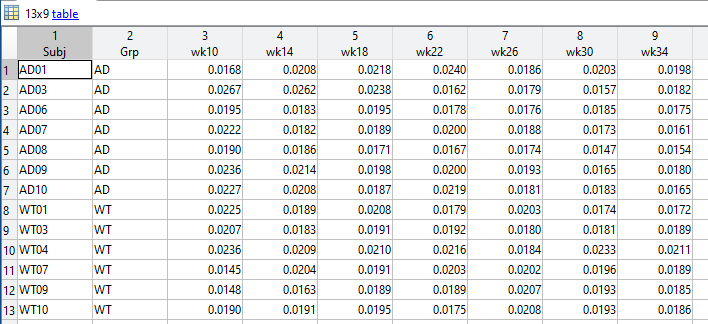

Tukey boxplot

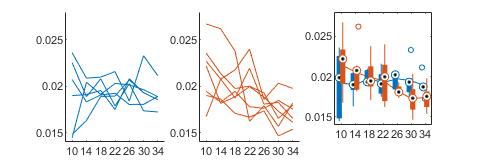

t = (10:4:34);  nt = length(t);
CDw = tbRaw(tbRaw.Grp == "WT",3:9).Variables;
CDa = tbRaw(tbRaw.Grp == "AD",3:9).Variables;

clr = lines(2);
figure('position',[.1 .1 3/4 1/4]*640);
for id=1:2
    if (id == 1),  CD = CDw;  else,  CD = CDa;  end
    subplot(1,3,id);  
        for is=1:size(CD,1)
            line(t,CD(is,:),'color',clr(id,:));
        end
        xlim([t(1)-2 t(end)+2]);  ylim([1.4 2.8]/100);
        set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));
end 
subplot(1,3,3);  hold on; 
    line(t,mean(CDw,1),'color',clr(1,:));
    line(t,mean(CDa,1),'color',clr(2,:));
    boxplot(CDw,'plotstyle','compact','colors',clr(1,:),'positions',t-0.5);
    boxplot(CDa,'plotstyle','compact','colors',clr(2,:),'positions',t+0.5);
    xlim([t(1)-2 t(end)+2]);  ylim([1.4 2.8]/100);
    set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));

- AD showed a clear trend of decreasing CD.

# T-test

Plot data.

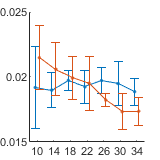

figure('position',[.1 .1 1/4 1/4]*640);  hold on;
for id=1:2
    if (id == 1),  CD = CDw;  else,  CD = CDa;  end
    errorbar(t-0.5+(id-1),mean(CD,1),tinv(0.95,size(CD,1)-1)*std(CD,0,1)/sqrt(size(CD,1)),'color',clr(id,:),'marker','.');
    xlim([t(1)-2 t(end)+2]);  ylim([1.5 2.5]/100);
    set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));
end

- lower CD in AD in later ages

## Paired t-test vs t1 (wk 10)

h = zeros(2,nt);
for id=1:2
    if (id == 1),  CD = CDw;  else,  CD = CDa;  end
    for it=1:nt
        h(id,it) = ttest(CD(:,1),CD(:,it));
    end
end
h

h =    NaN     0     0     0     0     0     0
   NaN     0     0     0     1     0     1


- AD became different at 26 and 34 woa, but not at 30 woa

T-test analysis was vulnerable to large noise at a specific time point (e.g., AD's t = 30 woa).

## T-test of AD vs. WT

h2 = zeros(1,nt);
for it=1:nt
    h2(it) = ttest2(CDa(:,it),CDw(:,it));
end
h2

h2 =      0     0     0     0     1     0     0


- AD became different only at 26 woa.

# LME

Prepare table.

tbCD = stack(tbRaw,3:9,"IndexVariableName","WeekStr","NewDataVariableName","CapDensity");
no = height(tbCD);
tbCD.Week = zeros(no,1);
for io=1:no
    wk = string(tbCD(io,:).WeekStr);
    wk = extractBetween(wk,3,4);
    tbCD(io,:).Week = str2num(wk);
end

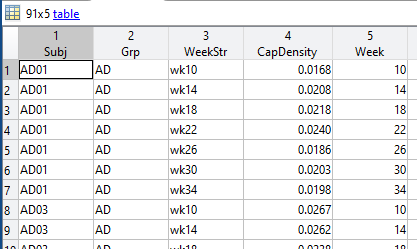

## WT - linear

D_i(t) = b0 + b1 * t + u0_i + eps  where i = Vessel

tbCDsub = tbCD(tbCD.Grp == "WT",:);  id = 1;
nos = height(tbCDsub);

lme2 = fitlmematrix([ones(nos,1),tbCDsub.Week], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              42
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC       BIC        LogLikelihood    Deviance
    -403.7    -396.75    205.85           -411.7  

Fixed effects coefficients (95% CIs):
    Name            Estimate      SE            tStat      DF    pValue        Lower          Upper     
    'Offset'          0.019315     0.0008236     23.452    40    5.4555e-25       0.017651       0.02098
    'Slope'         4.0316e-07    3.2592e-05    0.01237    40       0.99019    -6.5467e-05    6.6273e-05

Random effects covariance parameters (95% CIs):
Group: Subj (6 Levels)
    Name1         Name2         Type         Estimate      Low

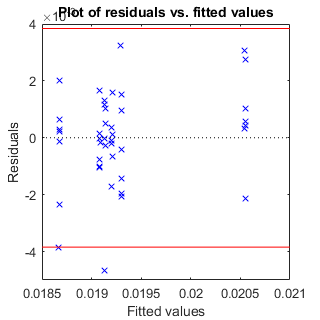

outlierRatio = 0.05;

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme2,'fitted');
resd = sort(abs(residuals(lme2)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme2)) > thr);
lme3 = fitlmematrix([ones(nos,1),tbCDsub.Week], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'}, ...
    'Exclude',iol)

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              41
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -402.88    -396.02    205.44           -410.88 

Fixed effects coefficients (95% CIs):
    Name            Estimate      SE            tStat       DF    pValue        Lower          Upper     
    'Offset'          0.019987    0.00077568      25.767    39    4.2289e-26       0.018418      0.021556
    'Slope'         -2.418e-05    2.9536e-05    -0.81867    39       0.41795    -8.3921e-05    3.5561e-05

Random effects covariance parameters (95% CIs):
Group: Subj (6 Levels)
    Name1         Name2         Type         Estimate    

compare(lme2,lme3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat      deltaDF    pValue
    lme2     4      -403.7    -396.75    205.85                                 
    lme3     4     -402.88    -396.02    205.44    -0.82819    0          0     


[lme2.Rsquared.Ordinary lme3.Rsquared.Ordinary]

ans =     0.1145    0.2022


The slope was NS.

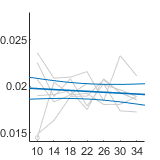

No significant difference from 10 woa, p(t1,tend)=0.466


ti = (t(1)-2):(t(end)+2);  clrbg = [1 1 1]*0.8;  limY = [1.4 2.8]/100;
lme = lme3;
[meanCD,seCD] = ExtractLmeFit1(lme,ti,'linear',t(1));
secfig1905c;

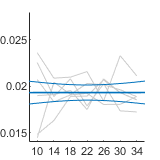

No significant difference from 10 woa, p(t1,tend)=0.991


lme = lme2;  iol = [];
[meanCD,seCD] = ExtractLmeFit1(lme,ti,'linear',t(1));
secfig1905c;

The slope was NS (p=0.6).

## WT - logistic

f(t;t0,tau) = 1 / ( 1 + exp(-(t-t0)/(tau/5.89)) )  where tau = the period for which 90% of the change occurs.

D_i(t) = b0 + b1 * f(t;t0,tau) + u0_i + eps

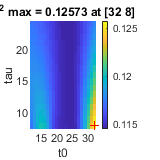

ct0 = (t(1)+2):(t(end)-2);
ctau = 8:24;  % ctau should longer than 8 weeks

r2 = zeros(length(ct0),length(ctau));
for it0=1:length(ct0)
    for itau=1:length(ctau)
        t0 = ct0(it0);
        tau = ctau(itau);
        lme4 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbCDsub.Week-t0)/(tau/5.89)))], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
            'FixedEffectPredictors', {'Offset','Amplitude'}, ...
            'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'});
        r2(it0,itau) = lme4.Rsquared.Ordinary;
        if r2(it0,itau) == max(r2(:))
            lme5 = lme4;
        end
    end
end
[r2max, idx] = FindMax(r2);  t0 = ct0(idx(1));  tau = ctau(idx(2));
figure('position',[.1 .1 1/4 1/4]*640);  hold on;
imagesc(ct0,ctau,r2');  axis tight;  colorbar;  xlabel('t0');  ylabel('tau');  title(['R^2 max = ' num2str(r2max,5) ' at ' mat2str([t0 tau])]);
line(t0,tau,'marker','+','color','r');

***R2 max at the boundary:  Don't keep going.  Use the linear.***

lmeWT = lme2;

lme5 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbCDsub.Week-t0)/(tau/5.89)))], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              42
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -17.283    -10.332    12.642           -25.283 

Fixed effects coefficients (95% CIs):
    Name               Estimate     SE          tStat       DF    pValue        Lower       Upper  
    'Offset'               1.941    0.042673      45.486    40    4.5929e-36      1.8548     2.0273
    'Amplitude'        -0.059565    0.092473    -0.64413    40       0.52317    -0.24646    0.12733

Random effects covariance parameters (95% CIs):
Group: Subj (6 Levels)
    Name1         Name2         Type         Estimate    Lower       Up

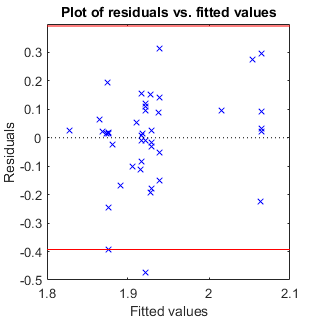

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme5,'fitted');
resd = sort(abs(residuals(lme5)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme5)) > thr);
lme6 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbCDsub.Week-t0)/(5.89*tau)))], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'}, ...
    'Exclude',iol)

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              41
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -25.251    -18.396    16.625           -33.251 

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE         tStat       DF    pValue        Lower      Upper  
    'Offset'             2.1521    0.25703      8.3731    39    3.0305e-10     1.6322      2.672
    'Amplitude'        -0.46175    0.56496    -0.81733    39       0.41871    -1.6045    0.68098

Random effects covariance parameters (95% CIs):
Group: Subj (6 Levels)
    Name1         Name2         Type         Estimate    Lower      Upper  
    

compare(lme5,lme6)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme5     4     -17.283    -10.332    12.642                               
    lme6     4     -25.251    -18.396    16.625    7.9676    0          0     


[lme2.Rsquared.Ordinary lme5.Rsquared.Ordinary]

ans =     0.1145    0.1257


[lme3.Rsquared.Ordinary lme6.Rsquared.Ordinary]

ans =     0.2022    0.2021


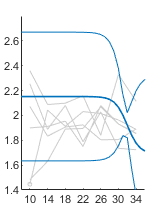

No significant difference from 10 woa, p(t1,tend)=0.284


lme = lme6;
[meanCD,seCD] = ExtractLmeFit1(lme,ti,'logistic',t(1),t0,tau);
secfig1905c;

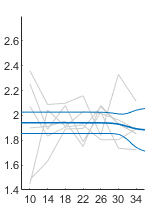

No significant difference from 10 woa, p(t1,tend)=0.583


lme = lme5;  iol = [];
[meanCD,seCD] = ExtractLmeFit1(lme,ti,'logistic',t(1),t0,tau);
secfig1905c;

## AD - linear

D_i(t) = b0 + b1 * t + u0_i + eps  where i = Vessel

tbCDsub = tbCD(tbCD.Grp == "AD",:);  id = 2;
nos = height(tbCDsub);

lme2 = fitlmematrix([ones(nos,1),tbCDsub.Week], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              49
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -456.85    -449.28    232.42           -464.85 

Fixed effects coefficients (95% CIs):
    Name            Estimate       SE           tStat     DF    pValue        Lower          Upper      
    'Offset'           0.023252    0.0008941    26.006    47    1.5049e-29       0.021454       0.025051
    'Slope'         -0.00018383    3.527e-05    -5.212    47     4.094e-06    -0.00025478    -0.00011287

Random effects covariance parameters (95% CIs):
Group: Subj (7 Levels)
    Name1         Name2         Type         Estimate      L

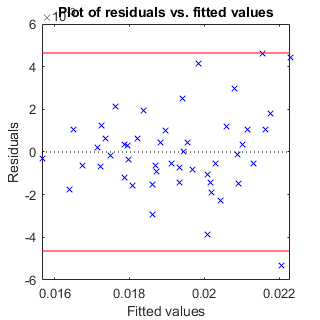

outlierRatio = 0.05;

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme2,'fitted');
resd = sort(abs(residuals(lme2)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme2)) > thr);
lme3 = fitlmematrix([ones(nos,1),tbCDsub.Week], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'}, ...
    'Exclude',iol)

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              48
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -456.17    -448.68    232.08           -464.17 

Fixed effects coefficients (95% CIs):
    Name            Estimate       SE            tStat     DF    pValue        Lower         Upper      
    'Offset'           0.023933    0.00087098    27.478    46    3.4652e-30       0.02218       0.025686
    'Slope'         -0.00020873    3.1828e-05    -6.558    46    4.2028e-08    -0.0002728    -0.00014466

Random effects covariance parameters (95% CIs):
Group: Subj (7 Levels)
    Name1         Name2         Type         Estimate     Lo

compare(lme2,lme3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat      deltaDF    pValue
    lme2     4     -456.85    -449.28    232.42                                 
    lme3     4     -456.17    -448.68    232.08    -0.68169    0          0     


[lme2.Rsquared.Ordinary lme3.Rsquared.Ordinary]

ans =     0.4265    0.5704


The slope is SIG.

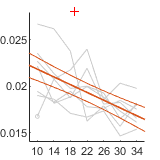

Became significantly different from 10 woa at 19 woa.


ti = (t(1)-2):(t(end)+2);  clrbg = [1 1 1]*0.8;  limY = [1.4 2.8]/100;
lme = lme3;
[meanCD,seCD] = ExtractLmeFit1(lme,ti,'linear',t(1));
secfig1905c;

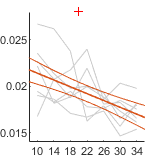

Became significantly different from 10 woa at 20 woa.


lme = lme2;  iol = [];
[meanCD,seCD] = ExtractLmeFit1(lme,ti,'linear',t(1));
secfig1905c;

The slope was NS (p=0.6).

## AD - logistic

f(t;t0,tau) = 1 / ( 1 + exp(-(t-t0)/(tau/5.89)) )  where tau = the period for which 90% of the change occurs.

D_i(t) = b0 + b1 * f(t;t0,tau) + u0_i + eps

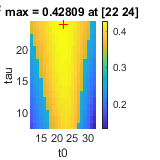

ct0 = (t(1)+2):(t(end)-2);
ctau = 8:24;  % ctau should longer than 8 weeks

r2 = zeros(length(ct0),length(ctau));
for it0=1:length(ct0)
    for itau=1:length(ctau)
        t0 = ct0(it0);
        tau = ctau(itau);
        lme4 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbCDsub.Week-t0)/(tau/5.89)))], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
            'FixedEffectPredictors', {'Offset','Amplitude'}, ...
            'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'});
        r2(it0,itau) = lme4.Rsquared.Ordinary;
        if r2(it0,itau) == max(r2(:))
            lme5 = lme4;
        end
    end
end
[r2max, idx] = FindMax(r2);  t0 = ct0(idx(1));  tau = ctau(idx(2));
figure('position',[.1 .1 1/4 1/4]*640);  hold on;
imagesc(ct0,ctau,r2');  axis tight;  colorbar;  xlabel('t0');  ylabel('tau');  title(['R^2 max = ' num2str(r2max,5) ' at ' mat2str([t0 tau])]);
line(t0,tau,'marker','+','color','r');

lme5 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbCDsub.Week-t0)/(tau/5.89)))], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              49
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -456.95    -449.39    232.48           -464.95 

Fixed effects coefficients (95% CIs):
    Name               Estimate      SE            tStat      DF    pValue        Lower         Upper    
    'Offset'             0.021397    0.00061047     35.051    47    2.4081e-35      0.020169     0.022626
    'Amplitude'        -0.0043788    0.00083749    -5.2285    47    3.8695e-06    -0.0060636    -0.002694

Random effects covariance parameters (95% CIs):
Group: Subj (7 Levels)
    Name1         Name2         Type         Estimate

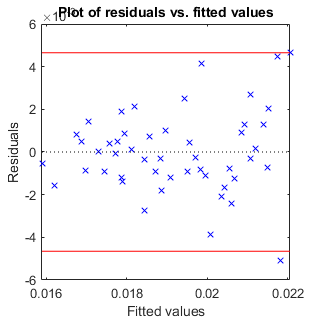

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme5,'fitted');
resd = sort(abs(residuals(lme5)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme5)) > thr);
lme6 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbCDsub.Week-t0)/(5.89*tau)))], tbCDsub.CapDensity, [ones(nos,1)], tbCDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'}, ...
    'Exclude',iol)

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              48
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -456.17    -448.68    232.08           -464.17 

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE           tStat     DF    pValue        Lower       Upper    
    'Offset'            0.07838    0.0090256    8.6842    46    2.9608e-11    0.060212     0.096547
    'Amplitude'        -0.11808     0.018005    -6.558    46    4.2033e-08    -0.15432    -0.081835

Random effects covariance parameters (95% CIs):
Group: Subj (7 Levels)
    Name1         Name2         Type         Estimate     Lower        

compare(lme5,lme6)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat      deltaDF    pValue
    lme5     4     -456.95    -449.39    232.48                                 
    lme6     4     -456.17    -448.68    232.08    -0.78646    0          0     


[lme2.Rsquared.Ordinary lme5.Rsquared.Ordinary]

ans =     0.4265    0.4281


[lme3.Rsquared.Ordinary lme6.Rsquared.Ordinary]

ans =     0.5704    0.5704


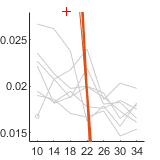

Became significantly different from 10 woa at 17 woa.


lme = lme6;
[meanCD,seCD] = ExtractLmeFit1(lme,ti,'logistic',t(1),t0,tau);
secfig1905c;

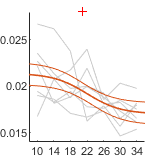

Became significantly different from 10 woa at 21 woa.


lme = lme5;  iol = [];
[meanCD,seCD] = ExtractLmeFit1(lme,ti,'logistic',t(1),t0,tau);
secfig1905c;

lmeAD = lme5;

save("fig1905 stat capillary density.mat");